warning('Convert from .mlx to .m')

warning('Extra offset needed in y plane for chassis point to face of pickup point')

warning('Units Used - (mm)')

%% Front Clevis Offsets

warning('Target for static Toe and Camber is 5deg')

 offset = [0, 0,0]

offset =      0     0     0



clevisOriginOffset = [ 0, 29, 0];

% GEN3_KinematicParameters

% Shim parts
vehicle.kinematics.front.camberShims_5219 = [0, 1.016, 0]; % CAD reference
vehicle.kinematics.front.camberShims_5220 = [0, 1.600, 0]; % CAD reference
vehicle.kinematics.front.camberShims_5221 = [0, 2.540, 0]; % CAD reference
vehicle.kinematics.front.camberShims_5222 = [0, 5.000, 0]; % CAD reference



vehicle.kinematics.rear.camberShims_3127 = [0, 1.016, 0]; % CAD reference
vehicle.kinematics.rear.camberShims_3140 = [0, 2.500, 0]; % CAD reference
vehicle.kinematics.rear.camberShims_3141 = [0, 5.000, 0]; % CAD reference
vehicle.kinematics.rear.camberShims_CAD_ERROR = [0, 1.6, 0]; % CAD reference


% Nominal position is 3
% From plane to wheel face is 6 degrees 

vehicle.ford.kinematcis.rear.tyreRadius = 350; %mm

vehicle.ford.kinematics.front.clevis.POS1 = [0, 28 , 25.0];
vehicle.ford.kinematics.front.clevis.POS2 = [0, 28 , 12.5];
vehicle.ford.kinematics.front.clevis.POS3 = [0, 28 , 0.00];
vehicle.ford.kinematics.front.clevis.POS4 = [0, 28 , -12.5];
vehicle.ford.kinematics.front.clevis.POS5 = [0, 28 , -25.0];

warning('Need Plane projection on for camber')

nominalCamberShim = 6.6; % CAD reference points have 6.6mm of shim on the front upright
vehicle.ford.kinematics.front.upperAArm.camberShimLeft =  [0, 1, 0];
vehicle.ford.kinematics.front.upperAArm.camberShimRight = vehicle.ford.kinematics.front.upperAArm.camberShimLeft;

vehicle.ford.kinematics.front.upperAArm.uprightConnector = [0, 82.5, 0];
vehicle.ford.kinematics.front.upperAArm.uprightBalljointAdjust = [0, 0, 7.5]; % measurement is in the uprights reference plane
% 3 discrete points would be enough of a change

vehicle.ford.kinematics.front.damper.chassisPickup = [-1948.9736, 420.5562, 562.2953];

vehicle.ford.kinematics.front.upperAArm.fore =      offset+ [-2175,      466.5289 , 294.92476]; % done
vehicle.ford.kinematics.front.upperAArm.ballJoint = offset+ [-1949.2757, 702.919,   331.0431 ]  + vehicle.ford.kinematics.front.upperAArm.camberShimLeft * 6;  % done
vehicle.ford.kinematics.front.upperAArm.aft =       offset+ [-1885,      466.5289,  294.92476]; % done


vehicle.ford.kinematics.front.lowerAArm.fore =      offset+ [-2148,      472, 66]; % done
vehicle.ford.kinematics.front.lowerAArm.ballJoint = offset+ [-2012.3338, 781.9798, 60.1016]; % done
vehicle.ford.kinematics.front.lowerAArm.aft =       offset+ [-1835,      472, 66];           % done

## Static Camber Contributions


vehicle.ford.kinematics.front.upperAArm.pivotPart = [0, 20, 0]; % CAD reference

vehicle.ford.kinematics.front.steeringRack.toeRodUpright = offset+ [-2144.1745, 765.550,  58.9963]; % done; % done
vehicle.ford.kinematics.front.steeringRack.toeRodChassis = offset+ [-2225,      420,      66];

% repeat the steering rack for code simplicity
vehicle.ford.kinematics.front.lowerAArm.toeRodUpright = vehicle.ford.kinematics.front.steeringRack.toeRodUpright;
vehicle.ford.kinematics.front.lowerAArm.toeRodChassis = vehicle.ford.kinematics.front.steeringRack.toeRodChassis;

vehicle.ford.kinematics.front.upright.rotationAxisOne = [-2025.8483, 839.9654, 207.83];
vehicle.ford.kinematics.front.upright.rotationAxisTwo = [-2027.1295, 960.6252, 222.0372];

vehicle.ford.kinematics.front.upright.wheelMatingFace2RotatationalAxis = []; %upright reference plane
vehicle.ford.kinematics.front.ARB.torsionBarEnd =           [-1912.5, 490, 12.5]; % done
vehicle.ford.kinematics.front.ARB.dropLinkConnection =      [-2089.8249, 490, 12.715]; % done
vehicle.ford.kinematics.front.ARB.dropLinkRotationAxis =    [-2085, 415, 340]; % done

vehicle.ford.kinematics.front.ARB.dropLinkHole =                [-2085, 487.4097, 374.0124]; % done
vehicle.ford.kinematics.front.ARB.transferLinkRotationAxis =    [-2042.5, 415, 340]; % done
vehicle.ford.kinematics.front.ARB.transferLinkHole =            [-2042.5, 473.8328, 367.6351]; % done
vehicle.ford.kinematics.front.ARB.transferLinkAArm =            [-2050.2524, 680.5690, 93.5423]; % done


% hole 1 3 5 - Radius 80 17.5 deg steps
% hole 2 4 - radius 65 12.5 deg steps
% 
% hole 1 2 3 radius 65 17.5 deg steps


vehicle.ford.kinematics.front.ARB.transferLinkAArm = [-2050.2524, 680.5690, 93.5423]; % done

## Picture

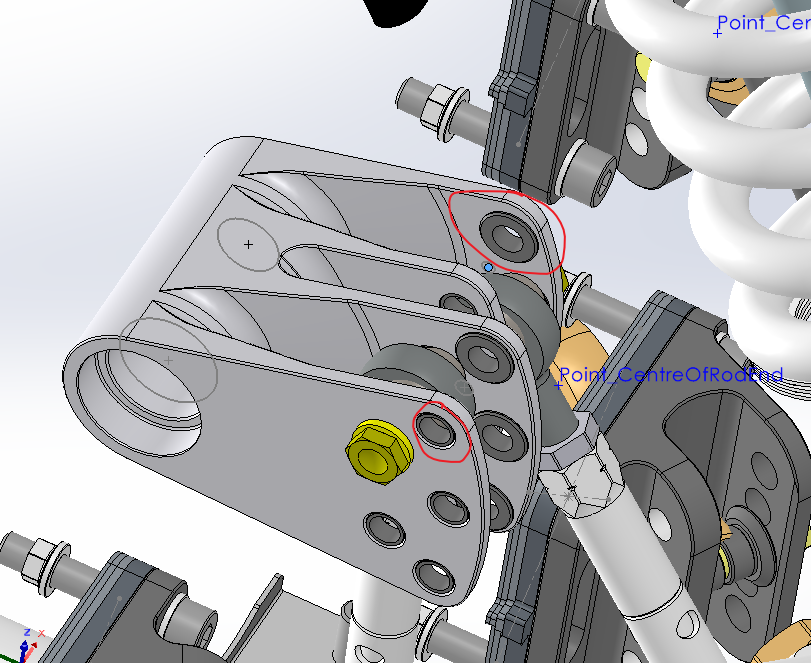

## Rear upper a-arm Offsets

warning('Need Plane projection on for camber')

nominalCamberShim = [0 ,6.6, 0]; % CAD reference points have 6.6mm of shim on the rear upright
clevisShimOffsetUFA = [0, 9, 0];
clevisShimOffsetUAA = [0, 9, 0];
clevisShimOffsetLFA = [0, 9, 0];
clevisShimOffsetLAA = [0, 9, 0];

vehicle.ford.kinematics.rear.upperAArm.camberShimLeft = [0, 1, 0]

vehicle = struct with fields:
    kinematics: [1×1 struct]
          ford: [1×1 struct]
            GM: [1×1 struct]
        toyota: [1×1 struct]


vehicle.ford.kinematics.rear.upperAArm.camberShimRight = vehicle.ford.kinematics.rear.upperAArm.camberShimLeft

vehicle = struct with fields:
    kinematics: [1×1 struct]
          ford: [1×1 struct]
            GM: [1×1 struct]
        toyota: [1×1 struct]



vehicle.ford.kinematics.rear.upperAArm.uprightConnector = [0, 82.5, 0];
vehicle.ford.kinematics.rear.upperAArm.uprightBalljointAdjust = [0, 0, 15]; % measurement is in the uprights reference plane
% 3 discrete points would be enough of a change

vehicle.ford.kinematics.rear.clevis.POS1 = [0, 28 , 25.0];
vehicle.ford.kinematics.rear.clevis.POS2 = [0, 28 , 12.5];
vehicle.ford.kinematics.rear.clevis.POS3 = [0, 28 , 0.00];
vehicle.ford.kinematics.rear.clevis.POS4 = [0, 28 , -12.5];
vehicle.ford.kinematics.rear.clevis.POS5 = [0, 28 , -25.0];

vehicle.ford.kinematics.rear.damper.chassisPickup = [680.5, 478.9772 , 588.8103];
vehicle.ford.kinematics.rear.rocker.ARBPickup =     [680.4979, 689.9381 , 18.1861];
vehicle.ford.kinematics.rear.rocker.damperPickup =  [680.3829, 693.2815 , 78.0929];
vehicle.ford.kinematics.rear.rocker.uprightPickup = [680.4974, 801.4376 , 41.009];

vehicle.ford.kinematics.rear.upperAArm.fore = [530.5, 417, 296] + clevisOriginOffset + clevisShimOffsetUFA;
vehicle.ford.kinematics.rear.upperAArm.aft = [830.5, 417, 296] + clevisOriginOffset + clevisShimOffsetUAA

vehicle = struct with fields:
    kinematics: [1×1 struct]
          ford: [1×1 struct]
            GM: [1×1 struct]
        toyota: [1×1 struct]


% vehicle.ford.kinematics.rear.upperAArm.ballJoint = [680.5, 682.3263 , 322.7942]; % experimentally found to have 0 camber shims
% found by using the rear camber correction, but using -6.6 which is the
% negation of the nominal length from the cad 

vehicle.ford.kinematics.rear.upperAArm.ballJoint = [680.5, 688.7929 , 324.3043];
% Connector piece and camber shim compensation are compelted through the
% kinematic sweep function
% Attempting to use the a arm place, central point :)

vehicle.ford.kinematics.rear.lowerAArm.fore = [470.5, 244 , 71] + clevisOriginOffset + clevisShimOffsetLFA;
vehicle.ford.kinematics.rear.lowerAArm.aft = [925.5, 244, 71] + clevisOriginOffset + clevisShimOffsetLAA;
vehicle.ford.kinematics.rear.lowerAArm.ballJoint = [680.4974, 801.4376, 42.009];

vehicle.ford.kinematics.rear.lowerAArm.toeRodUpright = [810.9965, 801.9947 , 42.1483];
vehicle.ford.kinematics.rear.lowerAArm.toeRodChassis = [911.6355, 384.1572, 65.5999];

vehicle.ford.kinematics.rear.upright.rotationAxis = [740.5586, 773.1527, 190.6875];

vehicle.ford.kinematics.rear.upright.wheelMatingFace2RotatationalAxis = [0, 80.25, 0]; %upright reference plane
    
vehicle.ford.steering.ratio = 58 / (2 * pi); % reference from tickford

vehicle.GM = vehicle.ford;
vehicle.toyota = vehicle.ford;


## VSD

vehicle.ford.minimumWheelbase = 2745.0; % mm
vehicle.ford.maximumWheelbase = 2767.5;% mm
vehicle.ford.maximumTrackWidthFront = 2000; % mm
vehicle.ford.maximumTrackWidthRear = 2000; % mm
vehicle.ford.maximumLength = 4863.0;% mm
vehicle.ford.frontAxleBodyWorkMaximum = 1934.5 + 10;% mm
vehicle.ford.rearAxleBodyWorkMaximum = 1959.5 + 10;% mm
vehicle.ford.roofHeight_neg510mm = 1165.5;% mm
vehicle.ford.roofheight_neg290mm = 1181.7;% mm
vehicle.ford.roofheight_pos305 = 1125.0;% mm
vehicle.ford.frontBumperLocation = [ -2988, 0 , -23.6];% mm
vehicle.ford.rearBumperLocation = [1874, 0, 527];% mm
vehicle.ford.rearWingPivotPointX = 1652.6 + [2 ,-5];% mm
vehicle.ford.rearWingPivotPointZ = 973.9 + [ 2, -5];% mm
vehicle.ford.rearWingElementDimensions = 1500 + [ 1, -1]; % mm
vehicle.ford.rearWingAngleMin = 9; % degrees
vehicle.ford.rearWingAngleMax = 10; % degrees
vehicle.ford.rearWingToDecklidSpoilerSpacingMax = [0, 270.5, 0] + [0, 3, 0;0, -3, 0]; % mm
vehicle.ford.rearWingDeflection = 0;
vehicle.ford.bonnetHeight_neg1500 = [0, 0, 792.8]; % + 3, -1mm
vehicle.ford.bonnetHeight_neg1950 = [0, 0, 771.9]; % + 3, -1mm
vehicle.ford.bonnetHeight_neg2400 = [0, 0, 720.2]; % + 3, -1mm
vehicle.ford.bonnetHeight_neg2800 = [0, 0, 579.6]; % + 3, -1mm
vehicle.ford.bootLidHeight_pos1290 = [0, 0, 864]; % + 3, -3mm
vehicle.ford.bootLidHeight_pos1675 = [0, 0, 791.3]; % + 3, -3mm
vehicle.ford.dashHeight = [0, 0, 787.0];
vehicle.ford.wheelArchLinersFront = true;
vehicle.ford.wheelArchLinersRear = true;


vehicle.toyota.minimumWheelbase = 2745.0; % mm
vehicle.toyota.maximumWheelbase = 2767.5;% mm
vehicle.toyota.maximumTrackWidthFront = 2000; % mm
vehicle.toyota.maximumTrackWidthRear = 2000; % mm
vehicle.toyota.maximumLength = 4740.1;% mm
vehicle.toyota.frontAxleBodyWorkMaximum = 1930.3 + 10;% mm
vehicle.toyota.rearAxleBodyWorkMaximum = 1958.5 + 10;% mm
vehicle.toyota.roofHeight_neg630mm = 1136.1% mm

vehicle = struct with fields:
    kinematics: [1×1 struct]
          ford: [1×1 struct]
            GM: [1×1 struct]
        toyota: [1×1 struct]


vehicle.toyota.roofheight_neg235_5mm = 1155.8;% mm
vehicle.toyota.roofheight_pos448 = 1098.5;% mm
vehicle.toyota.frontBumperLocation = [ -2980.8, 0 , -21.9];% mm
vehicle.toyota.rearBumperLocation = [1759.3, 0, 656.7];% mm
vehicle.toyota.rearWingPivotPointX = 1704.9 + [ 2 ,-5];% mm
vehicle.toyota.rearWingPivotPointZ = 1034.6 + [ 2, -5];% mm
vehicle.toyota.rearWingElementDimensions = 1400 + [ 1, -1]; % mm
vehicle.toyota.rearWingAngleMin = 9; % degrees
vehicle.toyota.rearWingAngleMax = 10; % degrees
vehicle.toyota.rearWingToDecklidSpoilerSpacingMax = [0, 343.4, 0] + [0, 3, 0;0, -3, 0]; % mm
vehicle.toyota.rearWingDeflection_mm_0 = 0; % mm
vehicle.toyota.rearWingDeflection_mm_80 = 4.5; % mm
vehicle.toyota.rearWingDeflection_mm_160 = 7.4; % mm
vehicle.toyota.rearWingDeflection_deg_0 = 0; % deg
vehicle.toyota.rearWingDeflection_deg_80 = 0.65; % deg
vehicle.toyota.rearWingDeflection_deg_160 = 1.00; % deg
vehicle.toyota.bonnetHeight_neg1550 = [0, 0, 790.6]; % + 3, -1mm
vehicle.toyota.bonnetHeight_neg2206 = [0, 0, 746.3]; % + 3, -1mm
vehicle.toyota.bonnetHeight_neg2500 = [0, 0, 662.9]; % + 3, -1mm
vehicle.toyota.bonnetHeight_neg2750 = [0, 0, 553.2]; % + 3, -1mm
vehicle.toyota.bonnetHeight_neg1397 = [0, 0, 820.8]; % + 3, -3mm
vehicle.toyota.bonnetHeight_neg1675 = [0, 0, 859.3]; % + 3, -3mm
vehicle.toyota.dashHeight = [0, 0, false];
vehicle.toyota.wheelArchLinersFront = true;
vehicle.toyota.wheelArchLinersRear = true;


vehicle.GM.minimumWheelbase = 2745.0; % mm
vehicle.GM.maximumWheelbase = 2767.5;% mm
vehicle.GM.maximumTrackWidthFront = 2000; % mm
vehicle.GM.maximumTrackWidthRear = 2000; % mm
vehicle.GM.maximumLength = 4876.1;% mm
vehicle.GM.frontAxleBodyWorkMaximum = 1933.3 + 10;% mm
vehicle.GM.rearAxleBodyWorkMaximum = 1952.6 + 10;% mm
vehicle.GM.roofHeight_neg625mm = 1123.3% mm

vehicle = struct with fields:
    kinematics: [1×1 struct]
          ford: [1×1 struct]
            GM: [1×1 struct]
        toyota: [1×1 struct]


vehicle.GM.roofheight_neg224_1mm = 1137.8; % mm
vehicle.GM.roofheight_pos605mm = 1081.1; % mm
vehicle.GM.frontBumperLocation = [ -3027.9, 0 , -25.1];% mm
vehicle.GM.rearBumperLocation = [1848.2, 0, 648.4];% mm
vehicle.GM.rearWingPivotPointX = 1703.8 + [ 2 ,-5];% mm
vehicle.GM.rearWingPivotPointZ = 977.2 + [ 2, -5];% mm
vehicle.GM.rearWingElementDimensions = 1500 + [ 1, -1]; % mm
vehicle.GM.rearWingAngleMin = 9; % degrees
vehicle.GM.rearWingAngleMax = 10; % degrees
vehicle.GM.rearWingToDecklidSpoilerSpacingMax = [0, 273.5, 0] + [0, 3, 0;0, -3, 0]; % mm
vehicle.GM.rearWingDeflection_mm_0 = 0; % mm
vehicle.GM.rearWingDeflection_mm_TBA1 = 0; % mm
vehicle.GM.rearWingDeflection_mm_TBA2 = 0; % mmø
vehicle.GM.rearWingDeflection_deg_0 = 0; % deg
vehicle.GM.rearWingDeflection_deg_TBA1 = 0; % deg
vehicle.GM.rearWingDeflection_deg_TBA2 = 0; % deg
vehicle.GM.bonnetHeight_neg1595 = [0, 0, 801.3]; % + 3, -1mm
vehicle.GM.bonnetHeight_neg2170 = [0, 0, 743.5]; % + 3, -1mm
vehicle.GM.bonnetHeight_neg2425 = [0, 0, 711.4]; % + 3, -1mm
vehicle.GM.bonnetHeight_neg2740 = [0, 0, 609.1]; % + 3, -1mm
vehicle.GM.bonnetHeight_neg1397 = [0, 0, 870]; % + 3, -3mm
vehicle.GM.bonnetHeight_neg1675 = [0, 0, 845.2]; % + 3, -3mm
vehicle.GM.dashHeight = [0, 0, 796]; %mm
vehicle.GM.wheelArchLinersFront = true; % boolean
vehicle.GM.wheelArchLinersRear = true; % boolean